# Simulation Results

clc;
clear;
close all;
[param, weather, route, driver] = loadData();

v2 = load("SimOutput_2023_05_07_18_46.mat");
v3 = load("SimOutput_2023_05_07_18_40.mat");

minutes(max(v2.out.tout / 60)) - minutes(max(v3.out.tout / 60))

ans = duration
   1.2937 min


## Plot

#### Velocity, SoC, Power vs Simulation time

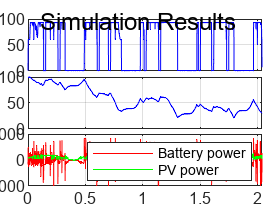

title = 'Simulation Results';
synchronizeXAxes = true;
xaxis = out.tout;
xlim = [0 xaxis(end)];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxis, out.Vel.Data * 3.6,'-','Color','b');
builder.setYlabel("Velocity [kmh^{-1}]");
builder.setXlim(xlim)

builder.startNewSubplot();
builder.addPlot(xaxis, out.Soc.Data * 100,'-','Color','b');
builder.setYlabel("State of charge [%]")
builder.setYlim([0 100])
builder.setXlim(xlim)

builder.startNewSubplot();
% builder.addPlot(xaxis, out.MotorPower.Data,'-','Color','b')
builder.addPlot(xaxis, out.BatteryPower.Data,'-','Color','r')
builder.addPlot(xaxis, out.PVpower.Data,'-','Color','g')
builder.setLegend("Battery power","PV power")
builder.setXlim(xlim)

builder.setXlabel("Simulation time [s]");
builder.drawNow()

#### SoC vs Distance

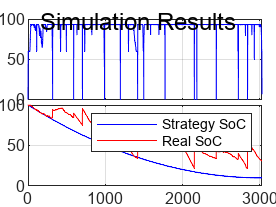

title = 'Simulation Results';
synchronizeXAxes = true;
xaxis = out.Pos.Data / 1000;
xlim = [0 xaxis(end)];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxis, out.Vel.Data * 3.6,'-','Color','b');
builder.setYlabel("Velocity [kmh^{-1}]");
builder.setXlim(xlim)

builder.startNewSubplot();
%change this line: linear to quadratic
State_of_charge_ref = SoCcontroller_quadratic(out.Pos.Data, driver.stopLocDist(end));
builder.addPlot(xaxis, State_of_charge_ref * 100,'-','Color','b');
builder.addPlot(xaxis, out.Soc.Data * 100,'-','Color','r');
builder.setYlabel("State of charge [%]")
builder.setYlim([0 100])
builder.setLegend("Strategy SoC","Real SoC")
builder.setXlim(xlim)

builder.setXlabel("Distance [km]")
builder.drawNow()